# Verfahren 1 - Iteration

v1T = tic;

## Schritt 0:

#### y-Achse

fY_WZrad = 0;
y = 0;
Y_shift = 0;

#### z-Achse

fZ_WZrad = 0;
z = 75;

#### C-Achse

[a,b,c] = deal(0);
zWst = 50;
zWz = 1;
dirFac = -1;
f_WSTrad = zWz / zWst * dirFac;
ga = 0;

#### A-Achse

A = 0;

### Umwandlungs der kartesischen Werkzeugkoordinaten in Polarkoordinaten

poi = [-60 0 -11.4937]';

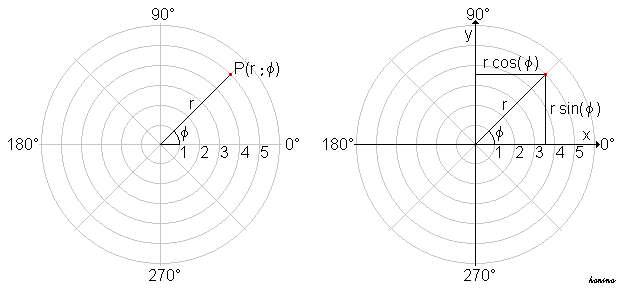

r_WZ = norm(poi(1:2));
phi_WZ = atan2(poi(2),poi(1))

phi_WZ =    3.141592653589793


h_WZ = poi(3);
% matlab function: [theta,rho,z] = cart2pol(x,y,z)

## Schritt 1:

### Definition der Funktion

syms z_soll B % zur Sicherheit, es ist unsicher, welches skript zuvor ausgeführt wurde
bfun = @(B,z_soll) pi - phi_WZ + asin((z - c - z_soll + B*fZ_WZrad + sin(A)*(y + Y_shift + B*fY_WZrad) + h_WZ*sin(A))./(r_WZ*cos(A)));
% bfun = @(B,z_soll) - phi_WZ - asin((z - c - z_soll + B*fZ_WZrad + sin(A)*(y + Y_shift + B*fY_WZrad) + h_WZ*sin(A))./(r_WZ*cos(A)))

## Schritt 2: Startwert für die Lösung

für jeden Iterationsschritt ein $z_{soll}$ definieren

z_soll = 50;   % [mm] aus CAD

B auf einen Schätzwert festlegen, 0 pi/2 pi etc. je nach dem wo die B-Achse startet und wie die WZ-Schneide liegt

B0 = pi*0.25

B0 =    0.785398163397448


B ausrechnen

B = bfun(B0,z_soll)

B =    0.429775431304528


## Schritt N:

n = 0;

Schritt 2 mit neuem B durchführen bis Differenz zwischen B alt und B neu < gewählter Toleranz

while sum(abs(B-B0)) > 1e-4
    n = n+1;
    conv(n) = sum(abs(B-B0));
    B0= B;
    B=  bfun(B0,z_soll)
end

B =    0.429775431304528


- Alternativ: nach Schritt 2:  mit fzero lösen 0 == Z - c + B*fZ_WZrad + sin(A)*(Y + Y_shift + B*fY_WZrad) + h_WZ*sin(A) + r_WZ*cos(A)*(sin(B + phi_WZ))-Z_soll nach B 

## Ausgabe

fprintf('Dauer Lösung durch Iteration: %.4f sec.\n',toc(v1T))

Dauer Lösung durch Iteration: 0.0998 sec.


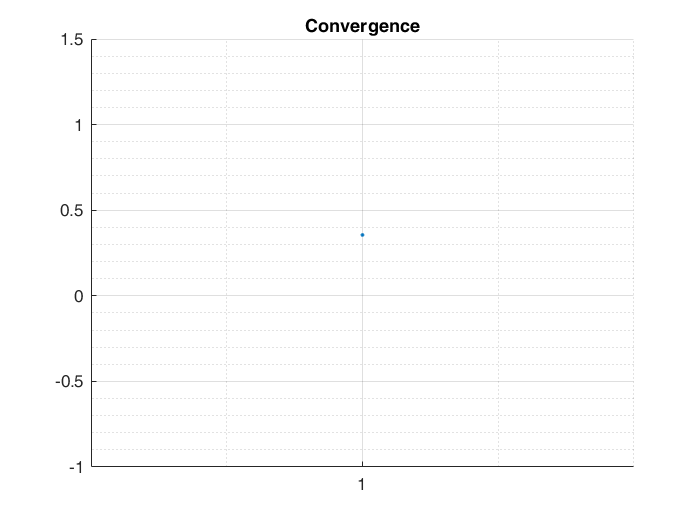

line((1:n),conv,'LineStyle','-','Marker','.')
grid on; grid minor; axH = gca;
set(axH(1),"XTick",1:n);
axH(1).Title.String = "Convergence";